# Tracking Closely Spaced Targets Under Ambiguity

This example shows how to track objects when the association of sensor detections to tracks is ambiguous. In this example, you use a single-hypothesis tracker, a multiple-hypothesis tracker, and a probabilistic data association tracker to compare how the trackers handle this ambiguity. To track, the maneuvering targets better, you estimate the motion of the targets by using various models.

## Introduction

Tracking is the process of estimating the situation based on data gathered by one or more sources of information. Tracking attempts to answer the following questions:

- How many objects are there?

- Where are the objects located in space?

- What is their speed and direction of motion?

- How do the objects maneuver relative to each other?

Trackers rely on sensor data such as radar detections. Sensors can generate two detections for two targets if the sensors can resolve the targets spatially. If two targets are closely spaced, they can fall within a single sensor resolution cell and the sensor reports only one detection of them. To illustrate the problem, the following figure shows a radar with a 1.5 degrees azimuth resolution. At a range of 20 km, the radar sensor bin has a width of above 540 m, which means that any detection reported from that range is located at the center of the bin, with a ±270 m uncertainty around it. Any two targets within this bin are reported as a single detection.

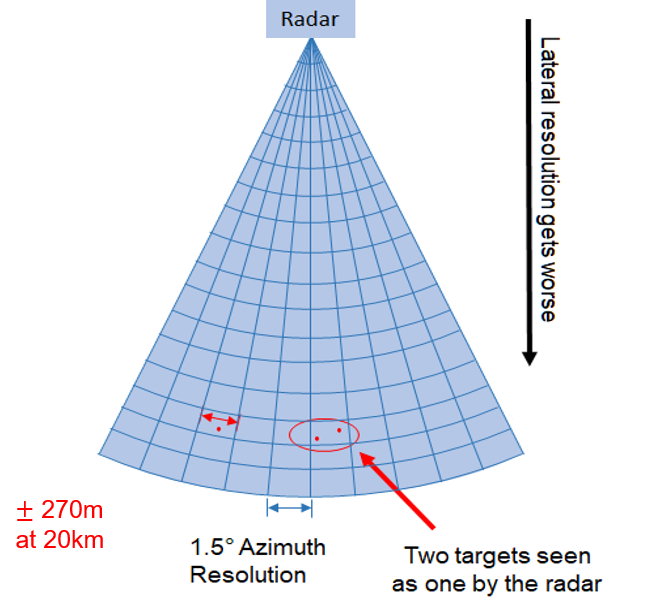

## Scenario

To demonstrate a case where sensor reports are ambiguously assigned to tracks, you create a simple scenario. In this scenario, a single radar object, located at the origin (not shown), scans a small region about 20 km from the radar. Initially, the radar reports about two detections per scan. When the detections are coming from a region around the X = 0, Y = -20 km position, the radar reports a single detection per scan for a while, followed by two radar detections reported from around Y = -19.5km and toward the sensor (up).

The scenario and detections log is already saved in a matfile. You can uncomment the lines below to regenerate the scenario and the synthetic detections.

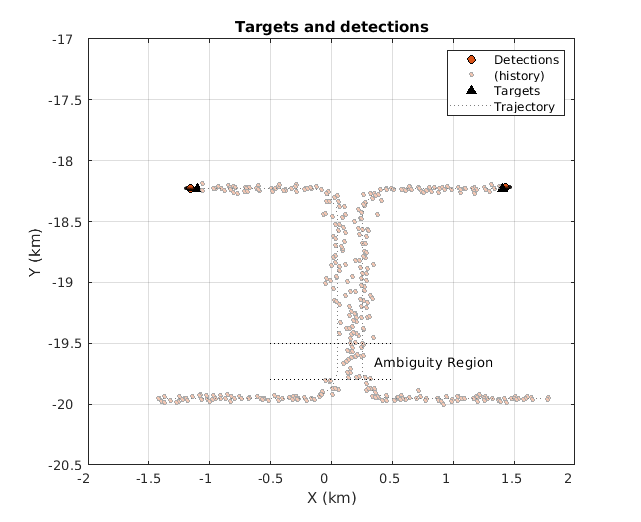

load ATCdata.mat
% scenario = helperCreateScenario;
% dataLog = helperRunDetections(scenario);
plotScenarioAndDetections(dataLog);

Looking only at the detections in this plot, it is reasonable to assume that there are two targets, but it is unclear whether their trajectories crossed. The targets did not cross as seen by their trajectory.

## Single-Hypothesis Tracker with Constant Velocity Model

The simplest choice of a multi-target tracker is a single-hypothesis tracker like the `trackerGNN`. You set it to use a score logic, to allow easier comparison with `trackerTOMHT` later in this example.

This example is small and does not require more than 20 tracks. The gate should be chosen to allow tracks to be established without spurious tracks and was increased from the default.

The sensor bin volume can be roughly estimated using the determinant of a detection measurement noise. In this case, the value is about 1e9, so you set the volume to 1e9. The value of beta should specify how many new objects are expected in a unit volume. As the number of objects in this scenario is constant, set beta to be very small. The values for probability of detection and false alarm rate are taken from the corresponding values of the radar.

numTracks = 20; % Maximum number of tracks
gate = 45;      % Association gate
vol = 1e9;      % Sensor bin volume
beta = 1e-14;   % Rate of new targets in a unit volume
pd = 0.8;       % Probability of detection
far = 1e-6;     % False alarm rate

You use a constant velocity extended Kalman filter. The `initCVFilter` function modifies the filter that `initcvekf` returns to allow for a higher uncertainty in the velocity terms and a higher horizontal acceleration in the process noise. These modifications are needed to track the targets in this scenario, which move at a high speed and maneuver by turning in the horizontal plane.

tracker = trackerGNN( ...
    'FilterInitializationFcn',@initCVFilter,...
    'MaxNumTracks', numTracks, ...
    'MaxNumSensors', 1, ...
    'AssignmentThreshold',gate, ...
    'TrackLogic', 'Score', ...
    'DetectionProbability', pd, 'FalseAlarmRate', far, ...
    'Volume', vol, 'Beta', beta);

The following line runs the scenario and produces the visualization.

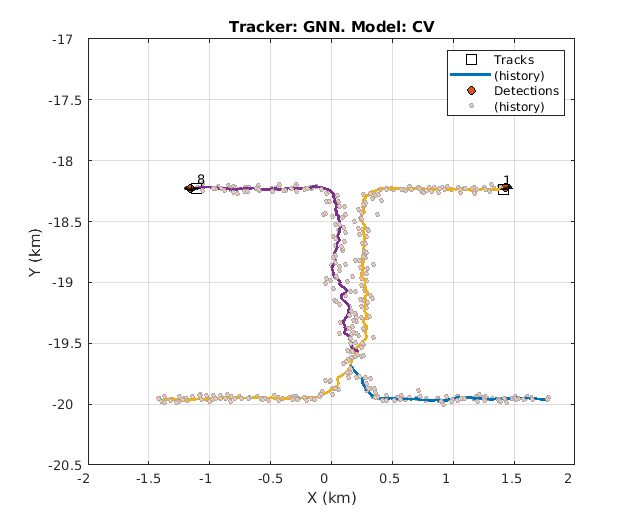

[trackSummary, truthSummary, trackMetrics, truthMetrics,timeGNNCV] = helperRunTracker(dataLog,tracker,false);

With the benefit of using a simulated ground truth, we can compare the results of the tracker with the truth, using `trackAssignmentMetrics` . The results show that there are two truth objects, but three tracks were generated by the tracker. One of the tracks did not survive until the end of the scenario, that is, it was dropped, and two other tracks did.

At the end of the scenario, truth object 2 was associated with track 8, which was created midway through the scenario after track 2 was dropped. Truth object 3 was assigned track 1 at the end of the scenario, but has two breaks.

Note that the establishment length of both truth objects was small while there were few false tracks, which means that the confirmation threshold is good.

disp(trackSummary)

    TrackID    AssignedTruthID    Surviving    TotalLength    DivergenceStatus
    _______    _______________    _________    ___________    ________________

       1               3            true           190             false      
       2             NaN            false           77             true       
       8               2            true           111             false      



disp(truthSummary)

    TruthID    AssociatedTrackID    TotalLength    BreakCount    EstablishmentLength
    _______    _________________    ___________    __________    ___________________

       2               8                192            1                  4         
       3               1                192            2                  2         



Use the `trackErrorMetrics` to analyze the quality of tracking in terms of position and velocity errors between the truth objects and the tracks associated with them. The results show that the position errors are about 50-60 m and the velocity errors are about 30 m/s RMS.

disp(trackMetrics)

    TrackID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       1       59.461    26.119     7.9331       3.495 
       2       51.803    39.433     5.7494      3.0362 
       8       62.914    28.877     7.2004      3.0465 



disp(truthMetrics)

    TruthID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       2       62.147    27.546     8.3597      3.9608 
       3       56.218    32.109     6.3234      2.6642 



## Single-Hypothesis Tracker with Interacting Multiple Models

The combination of a single-hypothesis tracker and a constant velocity filter could not track the maneuvering targets. This result is evident by the fact that one of the tracks stops and then a new track begins, while there are only two targets in the scenario. It is also evident from the inability to follow the target turns.

One option to improve the tracker is to modify the filter to be an interacting multiple-model (IMM) filter, which allows you to consider two or more motion models for the targets. The filter switches to the correct model based on the likelihood of one model over the other given the measurements. In this example, the targets move in a constant velocity until they turn at a constant rate, so you define an IMM filter with these two models using the `initIMMFilter` function.

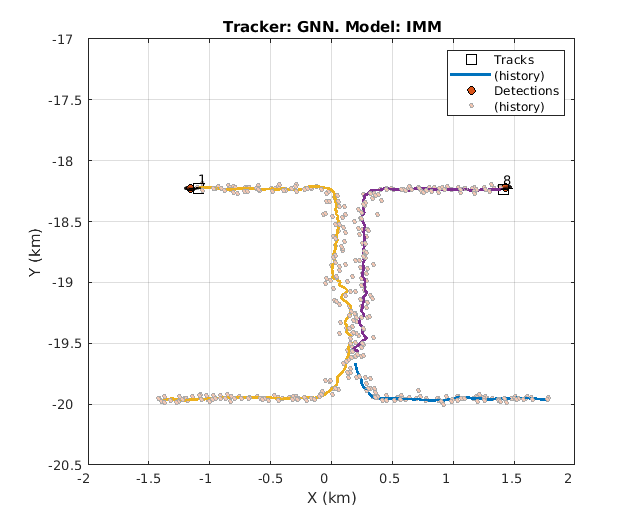

tracker = trackerGNN( ...
    'FilterInitializationFcn',@initIMMFilter,...
    'MaxNumTracks', numTracks, ...
    'MaxNumSensors', 1, ...
    'AssignmentThreshold',gate, ...
    'TrackLogic', 'Score', ...
    'DetectionProbability', pd, 'FalseAlarmRate', far, ...
    'Volume', vol, 'Beta', beta);
[trackSummary, truthSummary, trackMetrics, truthMetrics, timeGNNIMM] = helperRunTracker(dataLog,tracker,false);

The addition of an IMM filter enables the tracker to identify the target maneuver correctly. You can observe this conclusion by looking at the tracks generated during the target turns and notice how well both turns are tracked. As a result, truth object 2 has zero breaks, which you can see in the plot by the continuous history of its associated track.

However, even with the interacting models, one of the tracks breaks in the ambiguity region. The single-hypothesis tracker gets only one detection with that region, and can update only one of the tracks with it, coasting the other track. After a few updates, the score of the coasted track falls below the deletion threshold and the tracker drops the track.

disp(trackSummary)

    TrackID    AssignedTruthID    Surviving    TotalLength    DivergenceStatus
    _______    _______________    _________    ___________    ________________

       1               2            true           190             false      
       2             NaN            false           77             true       
       8               3            true           111             false      



disp(truthSummary)

    TruthID    AssociatedTrackID    TotalLength    BreakCount    EstablishmentLength
    _______    _________________    ___________    __________    ___________________

       2               1                192            0                  4         
       3               8                192            1                  2         



The use of an IMM also improved the tracking accuracy, as the position errors reduced to 40-60 meters, while the velocity errors reduced to 25-30 m/s. This improvement can be attributed to the lower process noise values used in the IMM for each model, which allow better smoothing of the noisy measurements.

disp(trackMetrics)

    TrackID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       1       52.445      22.4     7.6006      6.0031 
       2       48.149    35.239     6.5401      3.4887 
       8       34.787    20.279     5.2549      4.2032 



disp(truthMetrics)

    TruthID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       2       52.445      22.4     7.6006      6.0031 
       3        40.75    27.364     5.7772      3.9128 



## Multiple-Hypothesis Tracker with Constant Velocity Model

To resolve the problem of the broken track, use a multiple-hypothesis tracker (MHT), `trackerTOMHT`. In the ambiguity region, the tracker generates multiple hypotheses about the association of the detection with the tracks. In particular, it maintains one hypothesis that the first track is assigned this detection and another hypothesis that the second track is assigned the detection. By doing so, both tracks are kept alive, so that the tracker gets enough detections to resolve the ambiguity in the next updates.

`trackerTOMHT` uses the same parameters as `trackerGNN`, except:

- `AssignmentThreshold` allows a track to be considered unassigned even when there is an assigned detection. This setting allows multiple branches per track. However, the second element of the gate disallows new tracks from assigned detections, to reduce the total number of tracks and improve performance.

- `MaxNumHistoryScans` is increased to 10, to delay the `NScanPruning`.

- `MaxNumTrackBranches` is increased to 5, to allow more branches (hypotheses) per track.

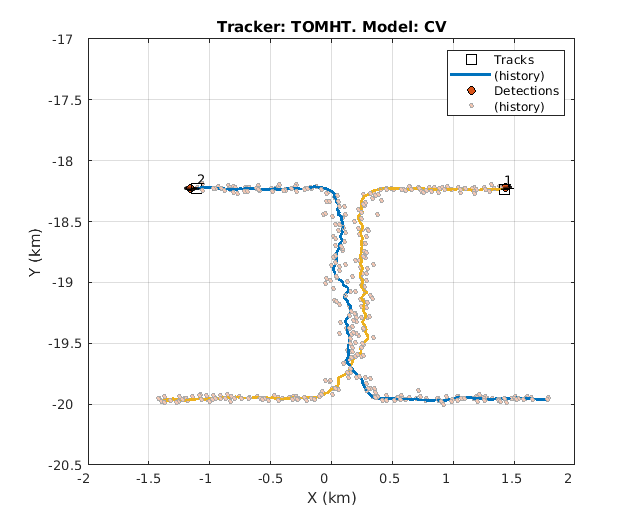

tracker = trackerTOMHT( ...
    'FilterInitializationFcn',@initCVFilter, ...
    'MaxNumTracks', numTracks, ...
    'MaxNumSensors', 1, ...
    'AssignmentThreshold', [0.2, 1, 1]*gate,...
    'DetectionProbability', pd, 'FalseAlarmRate', far, ...
    'Volume', vol, 'Beta', beta, ...
    'MaxNumHistoryScans', 10,...
    'MaxNumTrackBranches', 5,...
    'NScanPruning', 'Hypothesis', ...
    'OutputRepresentation', 'Tracks');

[trackSummary, truthSummary, trackMetrics, truthMetrics, timeTOMHTCV] = helperRunTracker(dataLog,tracker,false);

The results show the multiple-hypothesis tracker is capable of tracking the two truth objects throughout the scenario. For the ambiguity region, the MHT tracker formulates two hypotheses about the assignment:

- The detection is assigned to track 1.

- The detection is assigned to track 2.

With these hypotheses, both tracks generate branches (track hypotheses) that update them using the same detection. Obviously, using the same detection to update both tracks causes the tracks to become closer in their estimate, and eventually the two tracks may coalesce. However, if the duration of the ambiguous assignment is short, the tracker may be able to resolve the two tracks when there are two detections. In this case, you see that the two tracks cross each other, but the metrics show that the break count for each truth is 1, meaning that the true targets probably did not cross each other.

disp(trackSummary)

    TrackID    AssignedTruthID    Surviving    TotalLength    DivergenceStatus
    _______    _______________    _________    ___________    ________________

       1              3             true           190             false      
       2              2             true           191             false      



disp(truthSummary)

    TruthID    AssociatedTrackID    TotalLength    BreakCount    EstablishmentLength
    _______    _________________    ___________    __________    ___________________

       2               2                192            1                  2         
       3               1                192            1                  2         



In terms of tracking accuracy, the position and velocity errors of this tracker are similar to the ones from the combination of a single-hypothesis tracker with a constant velocity filter.

disp(trackMetrics)

    TrackID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       1       45.553    28.805     4.5831      3.2817 
       2       61.951    29.849     6.7165       2.733 



disp(truthMetrics)

    TruthID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       2       48.913    28.578     5.0099      3.2762 
       3       58.178    29.891     6.1356      2.8033 



## Multiple-Hypothesis Tracker with Interacting Multiple Models

Building on the success of using an multiple-hypothesis tracker with constant velocity to maintain continuous tracking, combine the tracker with the benefits of an IMM filter. The IMM filter may be more successful in preventing the track crossing as it improves the tracking when the targets turn. The following code configures `trackerTOMHT` with a `trackingIMM` filter.

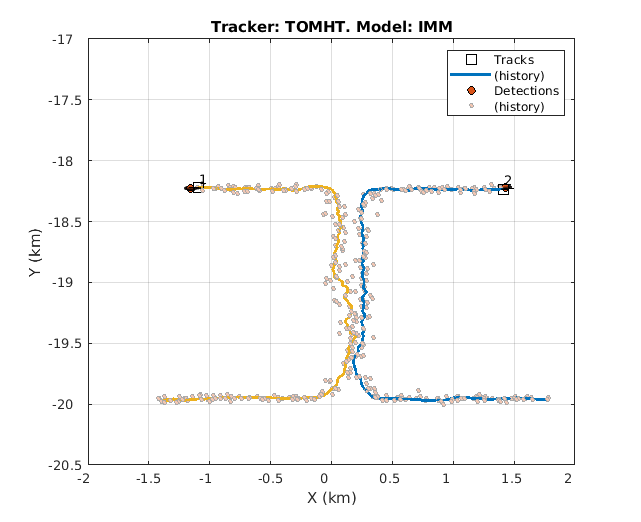

tracker = trackerTOMHT( ...
    'FilterInitializationFcn',@initIMMFilter, ...
    'MaxNumTracks', numTracks, ...
    'MaxNumSensors', 1, ...
    'AssignmentThreshold', [0.2, 1, 1]*gate,...
    'DetectionProbability', pd, 'FalseAlarmRate', far, ...
    'Volume', vol, 'Beta', beta, ...
    'MaxNumHistoryScans', 10,...
    'MaxNumTrackBranches', 5,...
    'NScanPruning', 'Hypothesis', ...
    'OutputRepresentation', 'Tracks');
[trackSummary, truthSummary, trackMetrics, truthMetrics, timeTOMHTIMM] = helperRunTracker(dataLog,tracker,false);

The plot shows that the two tracks did not cross. This result is also evident in the break count of the true targets below, which shows zero breaks.

You can also see the true path of the targets, shown in solid line.

disp(trackSummary)

    TrackID    AssignedTruthID    Surviving    TotalLength    DivergenceStatus
    _______    _______________    _________    ___________    ________________

       1              2             true           190             false      
       2              3             true           191             false      



disp(truthSummary)

    TruthID    AssociatedTrackID    TotalLength    BreakCount    EstablishmentLength
    _______    _________________    ___________    __________    ___________________

       2               1                192            0                  2         
       3               2                192            0                  2         



The tracking accuracy is similar to the combination of single-hypothesis tracker with IMM filter. Note that the truth accuracy and the associated track accuracy are the same because there was no break in the tracking throughout the scenario.

disp(trackMetrics)

    TrackID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       1       55.917    24.434     6.9456      5.5389 
       2        37.78    25.963      5.249      4.0935 



disp(truthMetrics)

    TruthID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       2       55.917    24.434     6.9456      5.5389 
       3        37.78    25.963      5.249      4.0935 



## Joint Probabilistic Data Association Tracker with Constant Velocity Model

Although the tracking metrics are greatly improved by using `trackerTOMHT` over `trackerGNN`, the computer processing time is also significantly increased. A Joint Probabilistic Data Association (JPDA) tracker, `trackerJPDA`, will allow you to explore further trade-off considerations. Unlike GNN, JPDA allows a single detection to be used for updating multiple tracks in its vicinity. Moreover, multiple detections can be clustered together with several tracks and update each of those tracks. This resolves the issue of the broken track. However, JPDA does not maintain multiple hypothesis over multiple scans, which makes it a sub-optimal approach as opposed to MHT.

`trackerJPDA` uses the same parameters as `trackerGNN` except:

- `ClutterDensity` is the ratio of `FalseAlarmRate` and `Volume`.

- `NewTargetDensity` replaces `Beta`.

- `TimeTolerance` allows for processing multiple detections from the scanning radar in a single cluster.

Additionally, set the `TrackLogic` to `Integrated` which is conceptually closer to the score logic used with the previous two trackers.

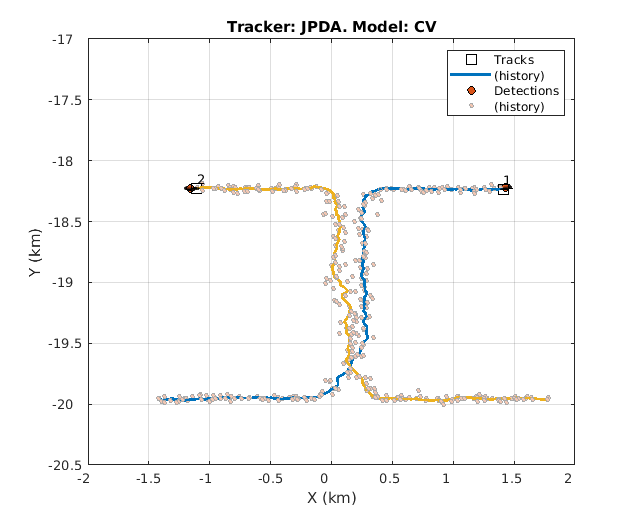

tracker = trackerJPDA(...
    'FilterInitializationFcn',@initCVFilter,...
    'MaxNumTracks', numTracks, ...
    'MaxNumSensors', 1, ...
    'AssignmentThreshold',gate, ...
    'TrackLogic','Integrated',...
    'DetectionProbability', pd, ...
    'ClutterDensity', far/vol, ...
    'NewTargetDensity', beta,...
    'TimeTolerance',0.05);

[trackSummary, truthSummary, trackMetrics, truthMetrics, timeJPDACV] = helperRunTracker(dataLog,tracker,false);

Although, trackerJPDA does not maintain multiple hypothesis, it allows both tracks to remain confirmed in the ambiguity region where only one detection is reported per update. Both tracks can be assigned to the detection with different probabilities. However, the tracks cross each other as observed before with the other trackers. The metrics break count of each truth is also 1.

disp(trackSummary)

    TrackID    AssignedTruthID    Surviving    TotalLength    DivergenceStatus
    _______    _______________    _________    ___________    ________________

       1              3             true           191             false      
       2              2             true           191             false      



disp(truthSummary)

    TruthID    AssociatedTrackID    TotalLength    BreakCount    EstablishmentLength
    _______    _________________    ___________    __________    ___________________

       2               2                192            1                  1         
       3               1                192            1                  2         



The tracking accuracy is on par with what is obtained with `trackerGNN` and `trackerTOMHT`.

disp(trackMetrics)

    TrackID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       1       44.918    29.911     5.1894      3.5599 
       2       58.904    31.484     7.0023      3.0944 



disp(truthMetrics)

    TruthID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       2       47.304    29.606     5.4677      3.5093 
       3       56.106    31.564     6.5976      3.1815 



## Joint Probabilistic Data Association Tracker with Interacting Multiple Models

As seen with the other two trackers, the turn before the ambiguity region is better addressed with interacting multiple models. `trackerJPDA` can also be used with `trackingIMM`, using the same `FilterInitializationFcn` as before.

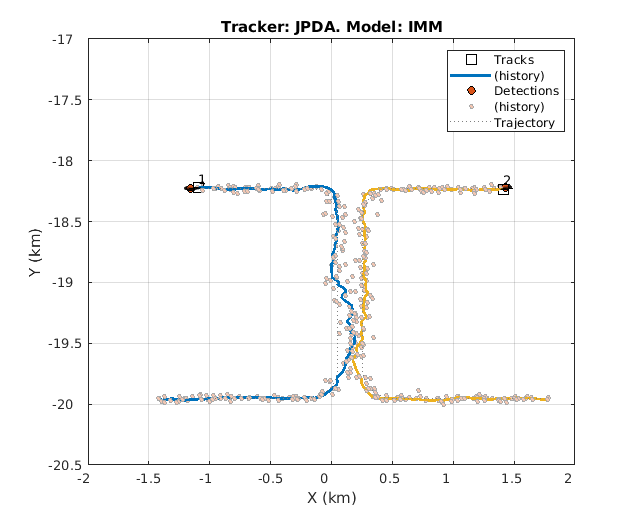

tracker = trackerJPDA( ...
    'FilterInitializationFcn',@initIMMFilter,...
    'MaxNumTracks', numTracks, ...
    'MaxNumSensors', 1, ...
    'AssignmentThreshold',gate, ...
    'TrackLogic','Integrated',...
    'DetectionProbability', pd, ...
    'ClutterDensity', far/vol, ...
    'NewTargetDensity', beta,...
    'TimeTolerance',0.05);

[trackSummary, truthSummary, trackMetrics, truthMetrics,timeJPDAIMM] = helperRunTracker(dataLog,tracker,true);

The results are comparable to `trackerTOMHT`, thanks to the Interacting Multiple Models, the targets are more precisely tracked during the turn and are sufficiently separated before entering the ambiguity region. Both tracks 1 and 2 are assigned to a target with zero break counts.

disp(trackSummary)

    TrackID    AssignedTruthID    Surviving    TotalLength    DivergenceStatus
    _______    _______________    _________    ___________    ________________

       1              2             true           191             false      
       2              3             true           191             false      



disp(truthSummary)

    TruthID    AssociatedTrackID    TotalLength    BreakCount    EstablishmentLength
    _______    _________________    ___________    __________    ___________________

       2               1                192            0                  1         
       3               2                192            0                  2         



Again, tracking accuracy results are similar to what is obtained previously using `trackerGNN` and `trackerTOMHT`.

disp(trackMetrics)

    TrackID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       1       57.172    27.523     7.6831      6.2685 
       2        39.21    29.184     6.1317       4.769 



disp(truthMetrics)

    TruthID    posRMS    velRMS    posANEES    velANEES
    _______    ______    ______    ________    ________

       2       57.172    27.523     7.6831      6.2685 
       3        39.21    29.184     6.1317       4.769 



## Time Performance Comparison

Another point of comparison for each tracker and filter combination is the runtime. The plot below shows records of the tracking loop duration. The results are normalized based on the runtime value of the GNN tracker with CV model.

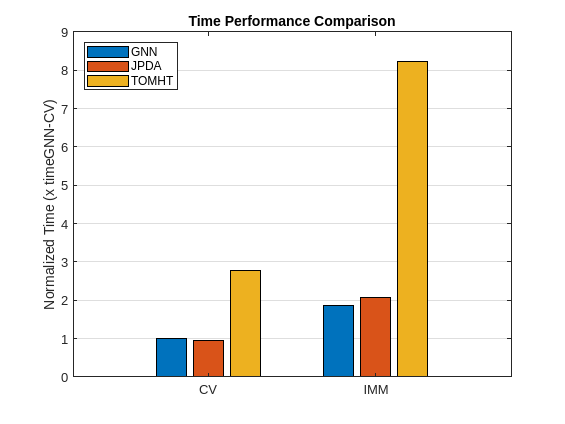

figure
c1 = categorical({'CV','IMM'});
timeData = [timeGNNCV timeJPDACV timeTOMHTCV ; timeGNNIMM timeJPDAIMM timeTOMHTIMM]/timeGNNCV;
bar(c1,timeData)
legend('GNN','JPDA','TOMHT','Location','northwest')
ylabel('Normalized Time (x timeGNN-CV)')
title('Time Performance Comparison')
ax = gca;
ax.YGrid = 'on';

The results show that GNN and JPDA can track the targets 5 to 6 times faster than MHT depending on the motion model. The IMM motion model makes all three trackers run 3 to 4 times slower. Note that each tracker processing time varies differently depending on the scenario's number of target, density of false alarms, density of targets, etc. This example does not guarantee similar performance comparison in different use cases.

## Summary

In this example, you created a scenario in which two maneuvering targets are detected by a single sensor, where some of their motion is within an area of ambiguity. You used six combinations of trackers and filters to show the contribution of each to the overall tracking. You observed that the constant velocity filter was less accurate in tracking the targets during their maneuver, which required an interacting multiple-model filter. You also observed the ability of MHT and JPDA to handle the case of ambiguous association of detections to tracks, and how it can be used to maintain continuous tracking while a single-hypothesis tracker cannot do that. Finally, you noticed the trade-offs between tracking results and processing time when choosing a tracker. In this case JPDA proves to be the best option. In different scenarios, you may require the more complex MHT when neither GNN nor JPDA gives acceptable tracking results. You may as well prefer GNN if there are less ambiguity regions or low clutter density.

*Copyright 2018-2019 The MathWorks, Inc.*